# Module 3, Lesson 1: Examples of normalizing data

This Live Script demonstrates the in-video examples for "Examples of Normalizing Data" 

## Load flights data

Load the data from September. 

flights = importFlightsData("flightsSep.csv");

Filter the table to only include flights from San Francisco (SFO) to Los Angeles (LAX)

flights = flights(flights.ORIGIN == "SFO" & flights.DESTINATION=="LAX",:)

flights = 1269×20 table
         AIRLINE          TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    __________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________

## Normal distributions

### Remove outliers from AIR_TIME variable

Consider the AIR_TIME column that contains how many minutes a flight was in the air. There's likely some natural variation in the flight time above and below some average from SFO to LAX, so you might expect this data to have a normal distribution. 

Make a histogram of the AIR_TIME column

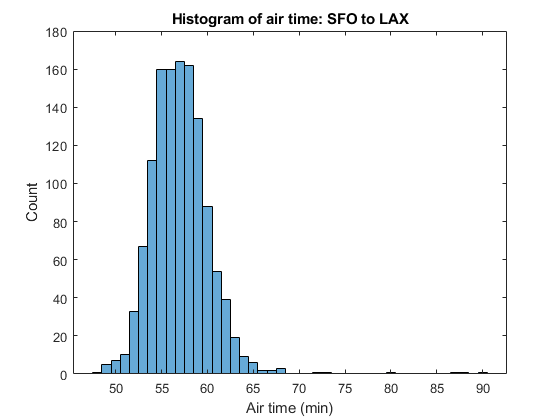

histogram(flights.AIR_TIME)
xlabel("Air time (min)")
ylabel("Count")
title("Histogram of air time: SFO to LAX")

Remove rows that contain outliers from the table. The "mean" method is appropriate since this data is fairly normally-distributed.

flights = rmoutliers(flights,"mean","DataVariables","AIR_TIME");

Remake the histogram without outliers. Notice the range is now smaller.

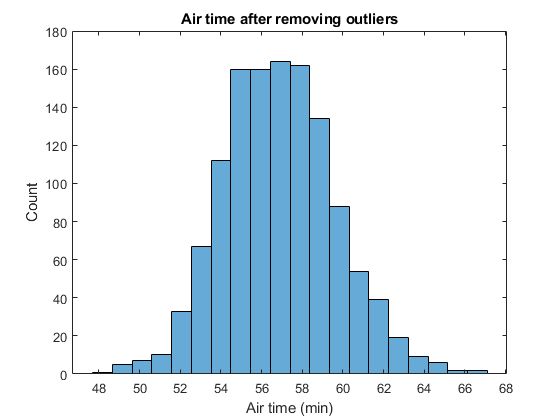

numBins = 20;
histogram(flights.AIR_TIME,numBins)
xlabel("Air time (min)")
ylabel("Count")
title("Air time after removing outliers")

### Normalize the AIR_TIME column

Use the `normalize()` function to normalize the AIR_TIME column. The default normalization method is a z-score.

flights.NORM_AIR_TIME = normalize(flights.AIR_TIME);

Remake the histogram of the normalized data. Can you find the number of bins that matches the above histogram?

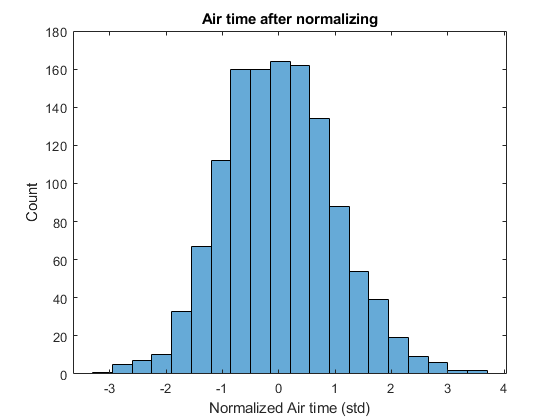

numBins = 20;
histogram(flights.NORM_AIR_TIME,numBins);
xlabel("Normalized Air time (std)")
ylabel("Count")
title("Air time after normalizing")

### Look at normalized values

You can think of the normalized AIR_TIME values as having "units" of standard deviations. So a value of +1 means the original value was 1 standard deviation above the mean, while a value of -2 implies the original value was 2 standard deviations below the mean

flights(:,["AIR_TIME","NORM_AIR_TIME"])

ans = 1260×2 table
    AIR_TIME    NORM_AIR_TIME
    ________    _____________

       55         -0.69092   
       62           1.7661   
       57         0.011093   
      NaN              NaN   
       62           1.7661   
       66           3.1701   
       56         -0.33991   
       58           0.3621   
       58           0.3621   
       60           1.0641   
       56         -0.33991   
       58           0.3621   
       61           1.4151   
       56         -0.33991   
       55         -0.69092   
       60           1.0641   


### Repeat for Departure delay

Use the same normalization for DEPARTURE_DELAY and create a scatter plot. Notice the range is different for departure delay, indicating that the z-score normalization may be inappropriate for this heavily skewed data.

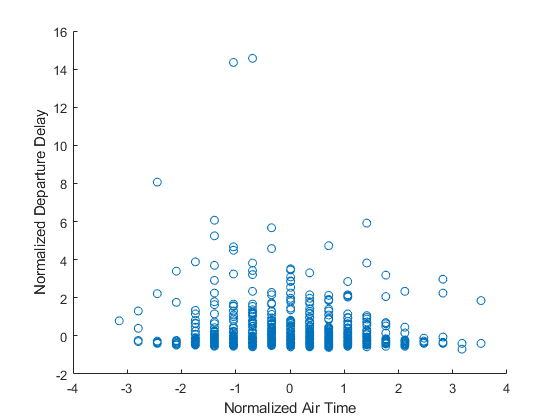

flights.NORM_DEPARTURE_DELAY = normalize(flights.DEPARTURE_DELAY);

scatter(flights.NORM_AIR_TIME,flights.NORM_DEPARTURE_DELAY)
xlabel("Normalized Air Time")
ylabel("Normalized Departure Delay")

## Uniform distributions

### Create a DEPARTURE_HOUR variable

Use the `hour()` function with the SCHEDULED_DEPARTURE time variable to get the hour in which flights were scheduled to depart. The rate of flights is fairly constant throughout the day, leading to a somewhat-uniform distribution. 

flights.DEPARTURE_HOUR = hour(flights.SCHEDULED_DEPARTURE_TIME);

Plot the data in a histogram

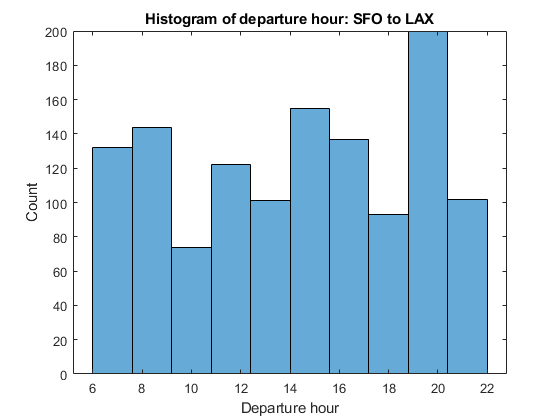

numBins = 10;
histogram(flights.DEPARTURE_HOUR,numBins)
xlabel("Departure hour")
ylabel("Count")
title("Histogram of departure hour: SFO to LAX")

### Choose a normalization method

Since this is not a normal distribution, the default normalization method with a z-score is not the best choice. The `normalize()` supports a variety of methods to accomodate other distributions. Specifically, you can choose from the following methods:

- `"zscore"`

- `"range"`

- `"norm"`

- `"scale"`

- `"center"`

For a uniform distribution, or another type distribution that has a well-defined maximum and minimum, the `"range"` method is a good choice. This will scale the data between 0 and 1, so the minimum is mapped to 0 and the maximum is mapped to 1.

You can use the drop-down menu below to compare between the different methods for this variable.

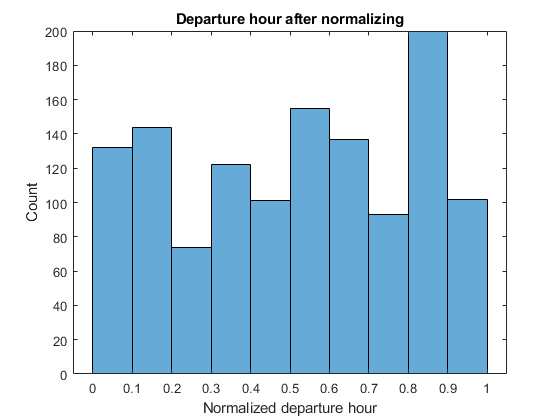

flights.NORM_DEPARTURE_HOUR = normalize(flights.DEPARTURE_HOUR,"range");
histogram(flights.NORM_DEPARTURE_HOUR,numBins)
xlabel("Normalized departure hour")
ylabel("Count")
title("Departure hour after normalizing")

## Skewed distributions

There are several skewed distributions in the flights dataset that are neither normal nor uniform. In these cases, you may want to use a "robust" option that is less susceptible to outliers.

### Histogram of a skewed variable

The departure delay is highly skewed to the right, meaning there are a small number of flights with very long delays. A standard z-score is not a good option to normalize this variable.  

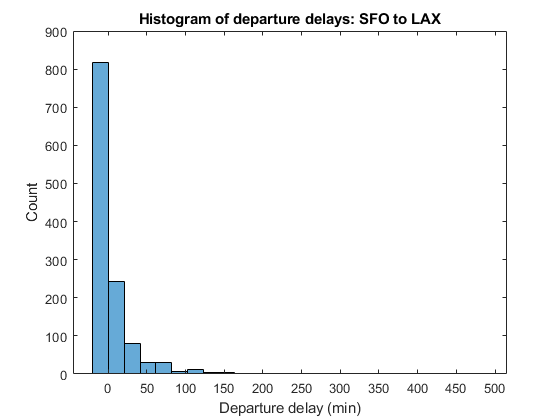

numBins = 25;
histogram(flights.DEPARTURE_DELAY,numBins);
xlabel("Departure delay (min)")
ylabel("Count")
title("Histogram of departure delays: SFO to LAX")

### Remove outliers using a robust method

First, remove outliers like you did for the `AIR_TIME `variable. Unlike of the `"mean"` method, the `"median"` method uses the more robust Median Absolute Deviation (MAD) statistic to identify outliers. Recall that you can also specify a `"ThresholdFactor"` to reject more or less data as outliers. In the code below, a fairly high threshold is used to only remove the most extreme outlier values.

flights = rmoutliers(flights,"median","ThresholdFactor",5, ...
    "DataVariables","DEPARTURE_DELAY");

### Normalize using a robust method

You can also use robust methods to normalize data. If you add the option `"robust"` after `"zscore"`, the data will be normalized using the MAD instead of the standard deviation.

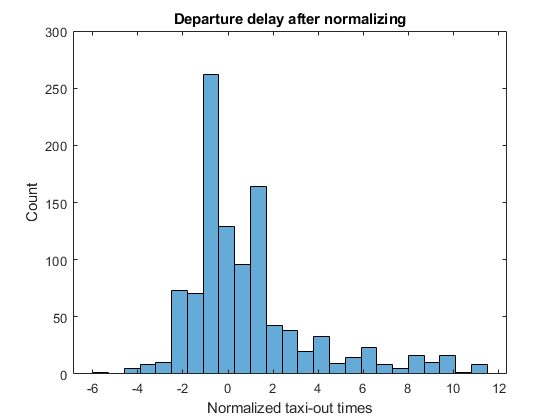

flights.NORM_DEPARTURE_DELAY = normalize(flights.DEPARTURE_DELAY,"zscore","robust");
histogram(flights.NORM_DEPARTURE_DELAY,numBins)
xlabel("Normalized taxi-out times")
ylabel("Count")
title("Departure delay after normalizing");